# Classify Age of Brain MRI Study Participants using Deep Learning

This example uses transfer learning to tune a pretrained neural network (ResNet-18) to perform chronological age classification on a brain MRI dataset. 

The anatomical MRI scans used in this example were obtained during a study [1] of social brain development conducted by researchers at the Massachusetts Institute of Technology (MIT). The full study dataset, including functional MRI (fMRI) scans revealing the participants' brain activity, are available for exploration and download via the [OpenNEURO resource](https://openneuro.org/datasets/ds000228/versions/1.1.0).

The dataset contains brain MRI scans obtained from 155 study participants. To illustrate the concepts of transfer learning, this example works with axial midslice 2D images extracted from the brain MRI scan 3D volumes. It shows how these 2D images can be classified into 3 categories according to the chronological age of the participant:

- Participants Aged 3-5

- Participants Aged 7-12

- Participants older than 18, classified as Adults

   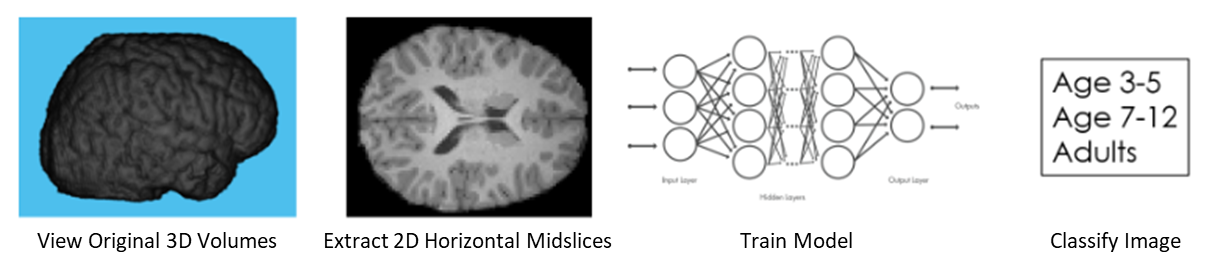

## Explore OpenNEURO Dataset

This example includes selections from the OpenNEURO dataset comprising 3D anatomical MRI scans of the brain taken from the 155 study participants of various ages: 

mriRootDataFolder = 'ds000228-1.1.0-subset';

In order to facilitate comparision between these brains of varying sizes and taken with differing MRI scanner protocols, the MIT researchers have also shared *preprocessed *brain volumes which are size-normalized and aligned to the Montreal Neurological Institute (MNI) template. These were computed using the freely-available [Statistical Parametric Mapping (SPM) software](https://www.fil.ion.ucl.ac.uk/spm/software/) [2]. This example will use this *derivative* dataset of preprocessed brain volumes:

mriDataFolder = fullfile(mriRootDataFolder, 'derivatives', 'preprocessed_data');

### Read 3D Volume Data

The 3D brain volumes are accessible as a [Neuroimaging Informatics Technology Initiative (NIfTI)](https://nifti.nimh.nih.gov/) formatted file that has been zipped for compression. The volume for each particpant can be read directly via the function `niftiread: `

vol = niftiread(fullfile(mriDataFolder,"sub-pixar001","sub-pixar001_normed_anat.nii.gz"));

### Visualize 3D Volume Data

The dataset additionally includes a pre-computed *mask *identifying the location of the skull in the volume. This can be used to perform *skull-stripping *on the volume: 

mask = niftiread(fullfile(mriDataFolder,"sub-pixar001","sub-pixar001_analysis_mask.nii.gz"));
vol = int16(vol) .* int16(mask); % Apply skull-stripping

Skull-stripping the volume reveals the outer surface of the brain's cortical surface. This can be visualized using `volshow`: 

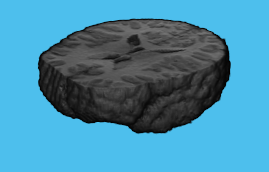

numSlices = size(vol,3);
imshow(vol(:,:,round(numSlices/2)));
volshow(vol(:,:,1:round(numSlices/2)),'CameraViewAngle',7.5);

### Explore Participant Data

The dataset root folder includes a tab-delimited file providing details about the study participants, including their age as well as other attributes. 

participantData = struct2table(tdfread([mriRootDataFolder '\participants.tsv']));
head(participantData) % view the first entries in the participant table to illustrate the original dataset contents

ans = 8×19 table
    participant_id     Age      AgeGroup    Child_Adult    Gender    Handedness    ToM_Booklet0x2DMatched    ToM_Booklet0x2DMatched0x2DNOFB    FB_Composite    FB_Group    WPPSI_BD_raw    WPPSI_BD_scaled    KBIT_raw    KBIT_standard    DCCS_Summary    Scanlog0x3A_Scanner    Scanlog0x3A_Coil    Scanlog0x3A_Voxel_slize    Scanlog0x3A_Slice_Gap
    ______________    ______    ________    ___________    ______    __________    ______________________    ______________________________    ____________    

The ages of the participants vary from 3 to 34. For this example, we will classify participants into 3 age categories:

participantData.AgeClass(participantData.Age >= 3 & participantData.Age < 6) = categorical("Ages3-5");
participantData.AgeClass(participantData.Age >= 7 & participantData.Age < 13) = categorical("Ages7-12");
participantData.AgeClass(participantData.Age >= 18) = categorical("Adults");

summary(participantData.AgeClass)

     Ages3-5       65 
     Ages7-12      57 
     Adults        33 


The dataset of 155 participants includes 65 children in the ages 3-5 class, 57 children in the ages 7-12 class, and 33 adults.

### Explore 2D Midslice Data

This deep learning example will use 2D axial midsection images extracted from each of the participant's 3D brain volumes. The 2D images are *axial slices*, referring to slices taken when viewing the brain volume from the top-down. The function `prepare2DImageDataset `performs the 2D image extraction and also normalizes the images by intensity, so the ensuing image classification will focus on structural image features. 

Calling `prepare2DImageDataset `on the source data folder returns the first 2D axial midslice image from the first participant file in each age class as exemplars:

exemplars = prepare2DImageDataset(mriDataFolder);

These exemplars can be visualized by age class: 

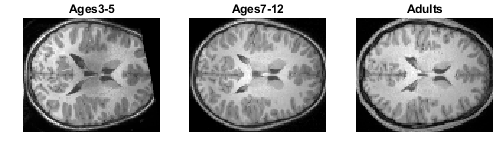

ageClasses = string(categories(participantData.AgeClass));

figure('Position',[10 10 500 150]);
tiledlayout(1,numel(ageClasses),'Padding','none','TileSpacing','none');

for ii=1:length(ageClasses)
    nexttile;
    imshow(mat2gray(exemplars{ii}));
    title(ageClasses((ii)));
end

These exemplars include the skull along with the brain for each subject image, and it can be clearly observed the brain-to-skull distance increases with each age class. Published literature indicates that brain volume and head circumference both increase during early childhood, but the brain volume decreases from adolescence onward while head circumference does not [4]. Thus, brain-to-skull distance is an obvious image feature that a human could readily learn and use to perform the age classification task. 

For this example, *skull stripping* will be applied for each of the MRI images. This will compel the network to learn less obvious features, not readily learned by a human, to distinguish between age classes. The published dataset includes a skull-stripping *mask* computed by SPM software [2] for each of the derived 3D volumes.

## Prepare Dataset for Deep Learning

### Extract, Normalize, and Augment 2D MRI Images

To prepare the dataset for deep learning, the function `prepare2DImageDataset` will be applied to all participant 3D brain volumes. 

The function requires a destination folder be specified, where the extracted and normalized 2D images will be stored: 

classifierDataFolder = ['2DImageSet_' datestr(datevec(now),30)];

The function `prepare2DImageDataset p`rovides the options to apply skull-stripping as described above as well as online *data augmentation*`:`

applySkullStripping = true;
applyAugmentation = true;

*Data augmentation *enlarges the image dataset prior to training further below. The study dataset contains a total of 155 images, which is a rather small dataset for deep learning training. Enlarging the image dataset can generally help to prevent a network from overfitting and memorizing the exact details of the training images. For small datasets especially, it can also avoid underfitting because of insufficient training data to achieve good model convergence. Enabling this option doubles the dataset size by adding copies of the MRI sections flipped 180 degrees. Performing this dataset enlargement *prior* to training is referred to as *offline* data augmentation. Further below, additional data augmentation will be applied *during* training, referred to as *online *data augmentation.

The function `prepare2DImageDataset `can now be called with the options and destination folder specified: 

prepare2DImageDataset(mriDataFolder, classifierDataFolder, applyAugmentation, applySkullStripping);

### Create Image Datastore and Visualize Images

This example illustrates supervised deep learning, which requires labeled training data. For the collection of 2D image files just produced, the subfolder names are the source of image labels, with images grouped into subfolders specifying the participant age category. 

Use an [`ImageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html?s_tid=doc_ta) object to conveniently represent and manage this collection of labeled 2D image files going forward. The `LabelSource` option is specified as `'foldernames'`:

mriImgds = imageDatastore(classifierDataFolder,'IncludeSubfolders',true,'LabelSource','foldernames','FileExtensions','.png');

`The shuffle` method for an` imageDatastore `object can be used to select a random image from each image class (age group):

mriImgdsRand = shuffle(mriImgds);
mriImgdsExamples = splitEachLabel(mriImgdsRand,int16(1)); % Select the firstmost image from the just-shuffled datastore for each age class
numLabels = length(mriImgdsExamples.Labels);

for ii=numLabels:-1:1
    [imgArray{ii},infoArray(ii)] = readimage(mriImgdsExamples,ii);
end

We can display these random selections from each age class to see how they compare side-by-side:

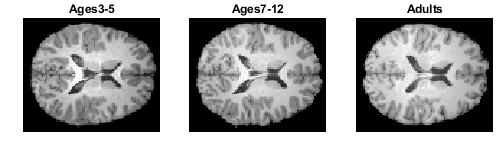

figure('Position',[10 10 500 150]);
tiledlayout(1,3,'Padding','none','TileSpacing','none');
for selCount=1:length(ageClasses)
    % Find the random-selected image in imageArray which pertains to the next age class for display
    idx = find(ageClasses(selCount) == [infoArray.Label]);
    
    % If image is a flipped image (from the offline data augmentation), then flip it back, so all images have the same orientation
    [~,fname] = fileparts(infoArray(idx).Filename);
    if startsWith(fname,'image2')
        img = imrotate(imgArray{idx},-180);
    else
        img = imgArray{idx};
    end
    
    % Show the random selected image for the next age class
    nexttile;
    imshow(mat2gray(img));
    title(infoArray(idx).Label);
end

Given the normalizations by image size and intensity as described above, no brain structural features obviously vary with age allowing one to readily distinguish between the age classes. 

The user is encouraged to verify this with additional randomized selections from each image set, to further demonstrate the lack of image features obviously suited for this classification task:

### Divide the Dataset for Training and Evaluation

Training a neural network requires the dataset be split between the:

- Training imageset, which is used to supply the network with images to learn the classification task during training

- Validation imageset, which is used to test the network's classification accuracy during training (online)

- Test imageset, which is used to test the network's classification accuracy and evaluate the network performance after training is completed (offline)

Use the [`splitEachLabel`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html?s_tid=doc_ta) function to divide the overall 2D midslice imageset into these smaller imagesets for training, validation, and testing. This is often done in two steps, beginning with the split creating the test imageset: 

[trainImgs,testImgs] = splitEachLabel(mriImgds,0.85,'randomized'); % Reserve 15 percent of overall dataset for testing

The training imageset is then further subdivided to reserve a portion for validation:

[trainImgs, valImgs] = splitEachLabel(trainImgs,0.8,'randomized'); % Reserve 20 percent of dataset available for training for online validation

These dataset splits are uniform across the three age classes. Of the total of 310 images from 155 participants, including the 2x offline data augmentation performed above, these splits result in the following image quantities:

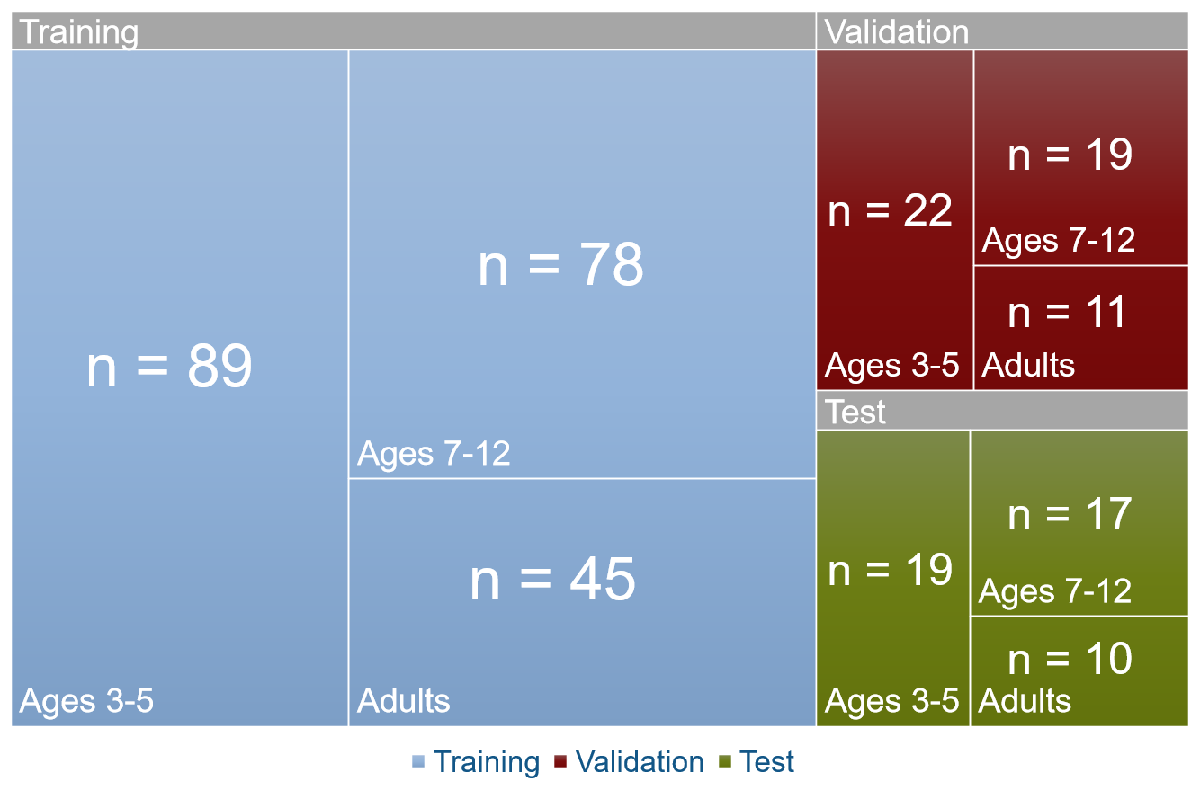

## Train ResNet-18 for Brain Age Classification

### Load the Pretrained Network (Resnet-18)

ResNet-18 is a convolutional neural network that is trained on more than a million 2D color images from the ImageNet database [[3]](https://www.mathworks.com/help/deeplearning/ref/resnet18.html#mw_591a2746-7267-4890-8390-87ae4dc7204c.mw_6dc28e13-2f10-44a4-9632-9b8d43b376fe). The network is 18 layers deep and can classify images into 1000 object categories, such as keyboard, mouse, pencil, and many animals. However, the network was not designed to predict the age of a person based on their brain anatomy. 

Extract the axial 2D midslice from any of the preprocessed MRI scans, and classify the image using ResNet-18. Note that input images may have sizes that are different from the pre-trained network's input layer. Use [`imresize`](https://www.mathworks.com/help/matlab/ref/imresize.html) to adjust the input image size.

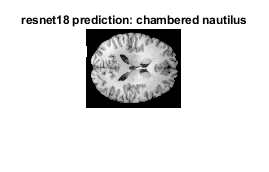

netName = 'resnet18';
net = resnet18();

netInputSize = net.Layers(1).InputSize;
inputImageSize = netInputSize(1:2);

img = imread(fullfile(classifierDataFolder, 'Adults', 'image_033.png'));
imgLabel = classify(net, imresize(img, inputImageSize));

figure('Position',[10 10 200 200]);
imshow(img);
title([netName ' prediction: ' char(imgLabel)]);

### Prepare Network for Transfer Learning

Transfer learning is a deep learning approach in which a model that has been trained for one task is used as a starting point to train a model for similar task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network from scratch.

To retrain ResNet-18 to classify the MRI scan imageset, use [`replaceLayer`](https://www.mathworks.com/help/deeplearning/ref/replacelayer.html) to change the last fully connected layer and the final classification layer of the network. [The layers to be replaced in ResNet-18](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html#MinimalTransferLearningExample-3) are named `'fc1000'` and `'ClassificationLayer_predictions'`, respectively. Set the new fully connected layer to have the same size as the number of classes in the new data set (3 in this example).

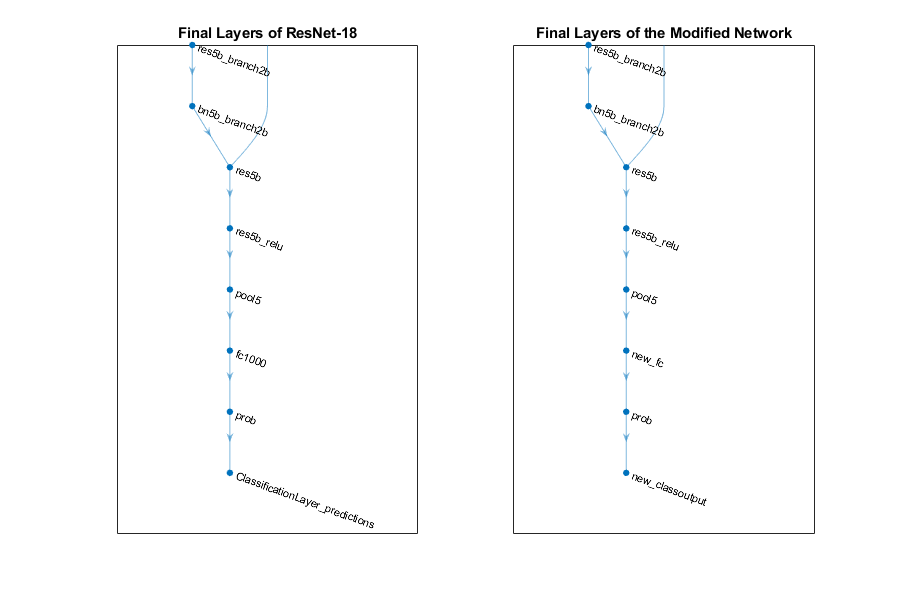

lgraph = layerGraph(net);
numClasses = numel(categories(mriImgds.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

figure("Position",[10 10 900 600])
subplot(1,2,1)
plot(layerGraph(net))
xlim ([0 4]);ylim([0 8])
title('Final Layers of ResNet-18')
subplot(1,2,2)
plot(lgraph)
xlim ([0 4]);ylim([0 8])
title('Final Layers of the Modified Network')

### Resize Images and Apply Online Augmentation

Before training, it will be required to resize the dataset images to make them compatible with the input size of the deep learning network. Determine the desired size of images to match that expected by the neural network being trained. For a transfer learning setup, this input image size can be determined by reviewing the first layer of the pretrained network:

net = resnet18();
imageSize = net.Layers(1).InputSize(1:2);

An [`augmentedImageDatastore`](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) can be used to dynamically resize the dataset images prior to training, validation, and testing operations during the deep learning workflow. As its name implies, it also provides the capacity to apply data augmentation operations, such as resizing, rotation, and reflection, to expose the network to a greater quantity and variety of images during training. This resizing and online data augmentation do not create any copies of the dataset files, in contrast to the offline image augmentation option above.

Load the images into 3 augmented image datastores - one each for the training imageset, validation imageset and test imageset, with resizing applied uniformly for each. The option for data augmentation is applied by configuring and applying an imageDataAugmenter object: 

imageAugmenter      = imageDataAugmenter('RandRotation',[-30,30]); % Use randomized rotation for further data augmentation

datastore_train     = augmentedImageDatastore(imageSize,trainImgs,'DataAugmentation',imageAugmenter);
datastore_validate  = augmentedImageDatastore(imageSize,valImgs);
datastore_test      = augmentedImageDatastore(imageSize,testImgs);

disp(table({'Train';'Validate';'Test'},[datastore_train.NumObservations;datastore_validate.NumObservations;datastore_test.NumObservations],'VariableNames',{'Datastore','Image Count'}))

     Datastore      Image Count
    ____________    ___________

    {'Train'   }        212    
    {'Validate'}         52    
    {'Test'    }         46    



### Specify Training Options for Transfer Learning

Prior to beginning training, the [trainingOptions](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function can be used to configure the learning algorithm and process for the model. Some of the common parameters adjusted for transfer learning are:

- `InitialLearnRate`

- `MiniBatchSize`

- `MaxEpochs`

- `ValidationFrequency`

The default `InitialLearnRate` value is applicable for training a network from scratch. For transfer learning, the features learned by the pretrained model should be retained in the transferred layers. To accomplish this, the learning is slowed for all layers: 

trainOpts.initLearnRate   = 0.001; % 10x reduction in initial learning rate

Above, the `WeightLearnRateFactor` was set to 10 for the final (replaced) layer, so the model will learn this new image classification task at a typical rate. 

This demonstration example uses a smaller-sized dataset, with 106-212 training images. During each validation period (an *epoch*), the model is shown *mini-batches *of training images during each *iteration* of the learning algorithm. The `MiniBatchSize `is computed by dividing evenly (if possible) into the number of training images. In this way, the model is shown the whole training image set between each validation:  

trainOpts.valFrequency    = 4; 
trainOpts.miniBatchSize   = floor(numel(datastore_train.Files)/trainOpts.valFrequency); % rounding needed in case offline data augmentation is disabled 

To speed the training demonstration for this example, the number of epochs will be reduced by 2x:

trainOpts.maxEpochs       = 15;

The  [trainingOptions](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function creates and returns a training options object based on these parameters:   

options = trainingOptions('sgdm', ...
    'MiniBatchSize',trainOpts.miniBatchSize, ...
    'MaxEpochs',trainOpts.maxEpochs, ...
    'InitialLearnRate',trainOpts.initLearnRate, ...
    'Shuffle','every-epoch', ... % this handles the case where the mini-batch size doesn't evenly divide the number of training images
    'ValidationData',datastore_validate, ... % source of validation data to evaluate learning during training
    'ValidationFrequency',trainOpts.valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress'); % display a plot of progress during training

A number of other advanced training options are available. For this example, default values are used for these for additional *h*. The effects of these hyperparameters could be further explored using [Bayesian optimization](https://www.mathworks.com/help/stats/bayesian-optimization-algorithm.html) to potentially optimizing training results or performance.

### Train the Network

By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU.

if gpuDeviceCount > 0
    gpudev = gpuDevice; % Use the default GPU device, if there's more than one
    reset(gpudev);
end

Train the network with the training imageset.  

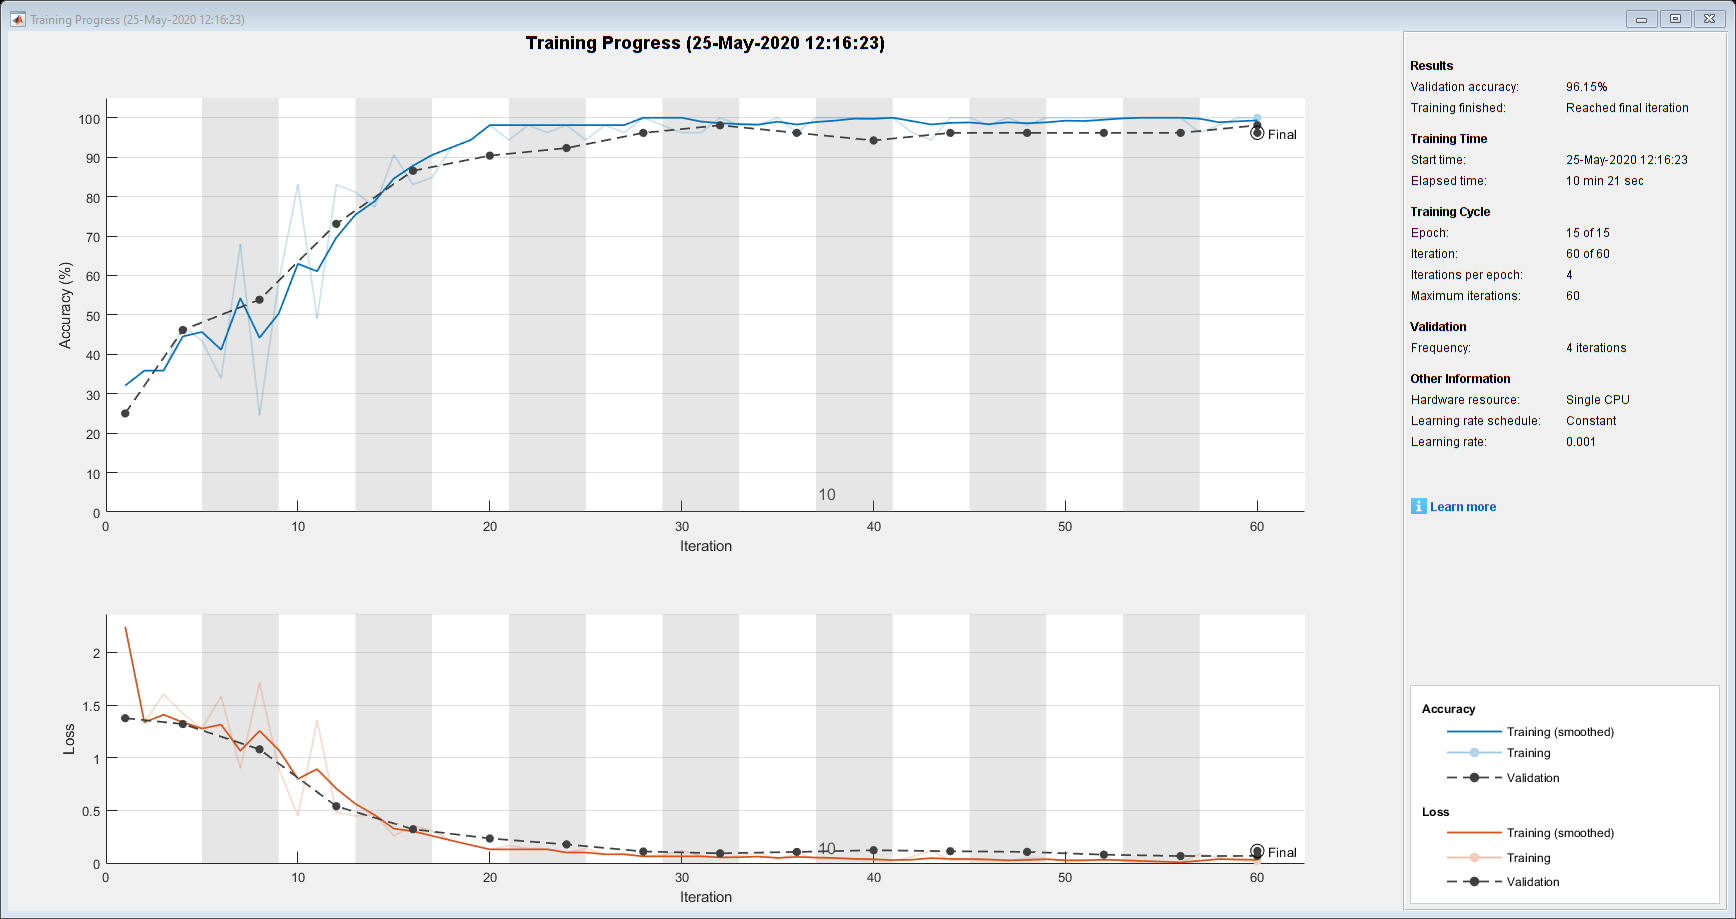

[mriNet,~] = trainNetwork(datastore_train, lgraph, options);

As the training progresses, the accuracy steadily increased. The validation accuracy, checked every 4 iterations, generally tracks the training accuracy, which reassures the network is not being overfit, i.e. learning specific training images rather than generalizable features identified from those training images. 

At the final iteration of training, it is typical to see a significant change (typically a drop-off) in the final validation accuracy. For networks containing batch normalization layers, such as the ResNet-18 model used here, the [final validation metrics are often different](https://www.mathworks.com/help/deeplearning/examples/monitor-deep-learning-training-progress.html) from the validation metrics evaluated during training. This is because the network undergoes a finalization step after the last iteration to compute the batch normalization layer statistics on the entire training data, while during training the batch normalization statistics are computed from the mini-batches [5]. It could be possible to reduce this effect by increasing the size of the mini-batches, to better match the entire dataset statistics, but this would increase the computational cost for each iteration. 

## Perform Brain Age Classification with Trained Network

Classify the test dataset images using the trained network: 

[test_preds,test_scores] = classify(mriNet,datastore_test);

This returns the predictions (`test_preds`) of brain age classes, as well as the confidence of the network (`scores`) for each prediction. 

### Determine Network Accuracy

How well did the network do? This accuracy can be computed by comparing the predictions to the test dataset labels:

accuracy = mean(test_preds == testImgs.Labels)

accuracy = 0.9783

Accuracies obtained will vary, given the randomized data split before training and data presentation during training. High accuracy levels (e.g. >80%) are typically obtained, which not only exceed that of chance (33%) but also the likely performance of a human classifier faced with the same task and training data. 

### Compute Confusion Matrix

Use a [`confusionchart`](https://www.mathworks.com/help/deeplearning/ref/confusionchart.html) to create a confusion matrix identifying which label were correctly predicted. This can help to identify where the network struggles the most within the test imageset.

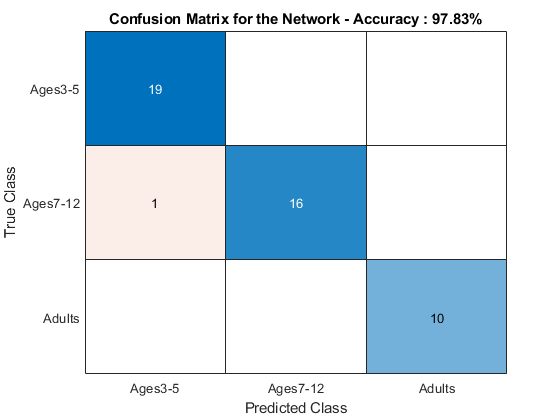

figure;
cm = confusionchart(testImgs.Labels,test_preds);
sortClasses(cm,["Ages3-5","Ages7-12","Adults"])
cm.Title = ['Confusion Matrix for the Network - Accuracy : ' num2str(100*round(accuracy,4)) '%'];

The confusion matrix reveals that errors are nearly always only off-by-one class, i.e. it is extremely rare to see an off-diagonal corner element where an adult is classified as a young child or vice versa. 

Furthermore, it is also rare to see any errors in the top row, i.e. the children aged 3-5 are nearly always correctly classified. This suggests the images of the youngest brains may contain the most distinctive features from the perspective of the network, as further explored in the next section. 

## Evaluation of the Trained Network

To understand how a trained network achieves good accuracy, network visualization techniques, such as class activation and occlusion sensitivity maps, can be used to identify which features of the test images are most important for the network's predictions. For instance, the ResNet-50 pretrained model can accurately identify images containing the French horn musical instrument, and occlusion sensitivity mapping shows that it does so by identifying the instrument's [distinctive valves and valve slides](https://blogs.mathworks.com/deep-learning/2017/12/15/network-visualization-based-on-occlusion-sensitivity/). 

### Visualize Features Used by Network via Occlusion

Occlusion sensitivity maps are computed by obstructing portions of the input image and observing its effect on the classification to determine which portions of the image are important in making the given prediction [6]. The [occlusionSensitivity](https://www.mathworks.com/help/deeplearning/ref/occlusionsensitivity.html) function computes these maps given a trained network and a set of test images.  

The local helper function viewOcclusionSensitivityMaps computes and displays occlusion sensitivity maps for correctly classified test images from a specific age class. For instance, display the occlusion sensitivity maps for a random selection of 3 correctly classified test images from the Ages3-5 class: 

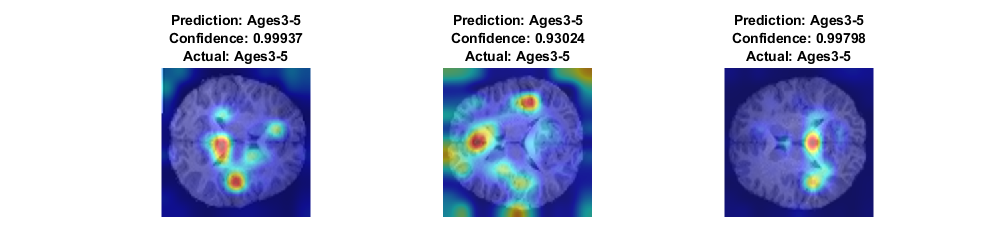

viewOcclusionSensitivityMaps("Ages3-5",3, mriNet, testImgs, test_preds, test_scores);

For classifying the youngest age class, the network typically reports very high confidence, consistent with the high accuracy observed. Often the occlusion sensitivity map will show the network is attuned to one or a few local brain features. These are often near the *ventricles* (channels for cerebrospinal fluid transport) at the center of each brain image. 

For comparison, the occlusion sensitivity maps can also be visualized for the two older age classes:

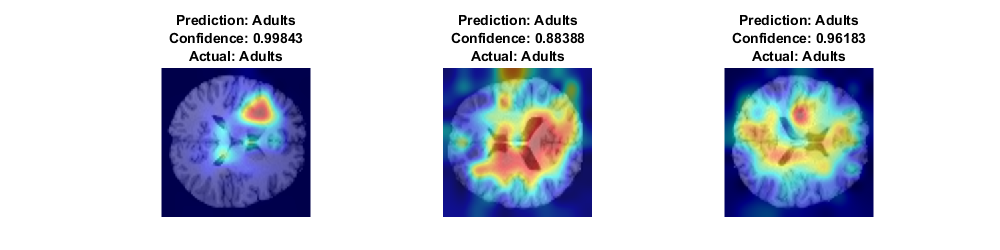

ageClass = categorical("Adults");
numSelections = 3;
viewOcclusionSensitivityMaps(ageClass,numSelections, mriNet, testImgs, test_preds, test_scores);

For the older age classes, the model's reported confidence is sometimes lower and features are not as consistently localized. Where localized features are found, they're more apt to include the cortical folds towards the edge of the brain volume. 

## References

[1] Richardson, H., Lisandrelli, G., Riobueno-Naylor, A., & Saxe, R. (2018). Development of the social brain from age three to twelve years. Nature Communications, 9(1), 1027. [https://www.nature.com/articles/s41467-018-03399-2](https://www.nature.com/articles/s41467-018-03399-2)

[2] Friston, K.J., Holmes, A.P., Worsley, K.J, *et al *(1994). Statistical parameteric maps in functional imaging: a general linear approach. Human Brain Mapping, 2(4), 189.

[3] *ImageNet*. [http://www.image-net.org](http://www.image-net.org)

[4] Bartholomeusz, H. H., Courchesne, E., & Karns, C. M. (2002). Relationship Between Head Circumference and Brain Volume in Healthy Normal Toddlers, Children, and Adults. *Neuropediatrics*, *33*(05), 239–241. [https://doi.org/10.1055/s-2002-36735](https://doi.org/10.1055/s-2002-36735)

[5] Li, X., Chen, S., Hu, X., & Yang, J. (2018). Understanding the Disharmony between Dropout and Batch Normalization by Variance Shift. Retrieved from [http://arxiv.org/abs/1801.05134](http://arxiv.org/abs/1801.05134) 

[6] Zeiler, M. D., & Fergus, R. (2014). Visualizing and Understanding Convolutional Networks. In Fleet D., Pajdla T., Schiele B., & Tuytelaars T. (eds.) Computer Vision -- ECCV 2014. ECCV 2014. Lecture Notes in Computer Science, vol 8689. Springer, Cham. [https://doi.org/10.1007/978-3-319-10590-1_53](https://doi.org/10.1007/978-3-319-10590-1_53)

## Helper Functions

function viewOcclusionSensitivityMaps(ageClass,nSelections, mriNet, testImgs, test_preds, test_scores)

figure("Position",[10 10 1000 250])

netInputSize = mriNet.Layers(1).InputSize;
inputImageSize = netInputSize(1:2);

% Create a randomized set of indices into the test image datastore
selectionIdxs = randperm(length(testImgs.Files));

% Visualize a random selection of correctly predicted images for each age class
tiledlayout('flow'); % up to 5 selections per row

selCount = 1;
mapCount = 1;
while mapCount <= nSelections
    selIdx = selectionIdxs(selCount); % A randomly-selected image in the test image set
    currLabel = testImgs.Labels(selIdx);
    
    if currLabel == ageClass && currLabel == test_preds(selIdx) % Selected image is of the specified age class and has been correctly classified
        img = imresize(testImgs.readimage(selIdx),inputImageSize);
        scoreMap = occlusionSensitivity(mriNet, img, test_preds(selIdx));
        
        nexttile;
        imshow(img);
        hold on
        imagesc(scoreMap,'AlphaData',0.5); % Overlay the score map onto the image with transparency
        
        colormap jet
        title([ ...
            "Prediction: " + string(test_preds(selIdx)) ,...
            "Confidence: " + num2str(max(test_scores(selIdx,:))) , ...
            "Actual: " + string(testImgs.Labels(selIdx))], ...
            'Interpreter', 'none');     
        
        mapCount = mapCount + 1; 
    end
    
    selCount = selCount + 1;
end

end

Copyright 2020 The MathWorks, Inc.